# Trabajo practico integrador

 

#### Evolucion de la temperatura a lo largo de la barra de acero en el tiempo

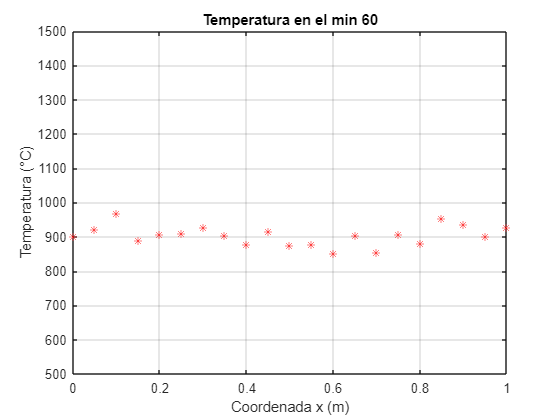

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;

for i = 1:n
    plot(x,T(i,:),'r*')
    title(sprintf('Temperatura en el min %d',i-1))
    xlabel('Coordenada x (m)')
    ylabel('Temperatura (°C)')
    grid on
    ylim([500 1500])
    pause(1 -0.6)
end

#### Temperatura promedio de la barra en el tiempo

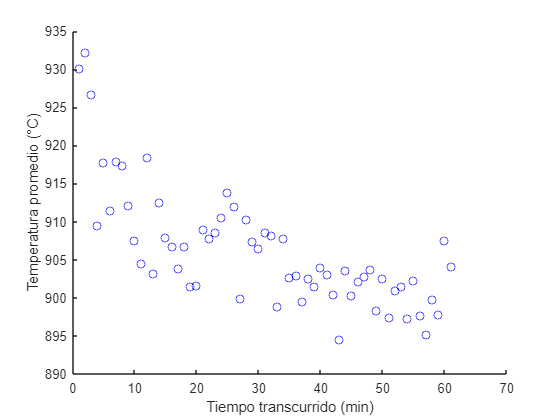

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;

[xx,tt] = meshgrid(x,t);
clf
for i = 1:n
    TemperaturaPromedio = promedio(T(i,:));
    hold on
    plot(i,TemperaturaPromedio,'bo')
    xlabel('Tiempo transcurrido (min)')
    ylabel('Temperatura promedio (°C)')
    hold off
end

#### Grafico de la temperatura [°C] en funcion del tiempo [s] y el largo de la barra [m]

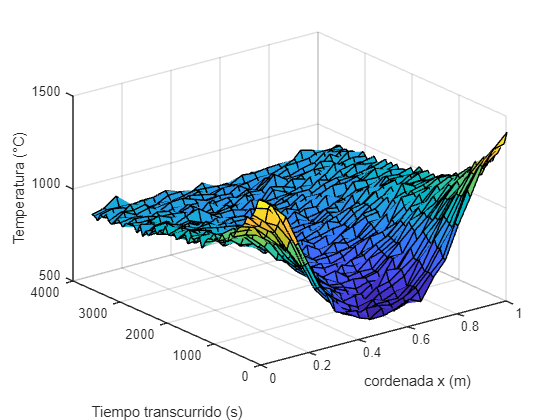

surf(xx,tt,T)
xlabel('cordenada x (m)')
ylabel('Tiempo transcurrido (s)')
zlabel('Temperatura (°C)')

## Ajuste discreto

A diferencia de un ajuste lineal, donde la funcion de ajuste es la ecuacion de una recta, o en el caso de dos variables, de un plano $\mathrm{F}\left(x,y\right)=\beta_{0\;} +\beta_1 *x_i \;+\beta_2 *\textrm{yi}\;$ .Se propone la función de ajuste: $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)e^{-c_3 t} \;\left\lbrack \textrm{◦C}\right\rbrack$ que predice la temperatura a lo largo de la barra para cada instante de tiempo, pero se desconocen las constantes $c_1 ,c_2 \;y\;c_3$

Se buscaran valores para $$c_1 ,c_2 \;y\;c_3$$ que minimicen el error cuadratico medio (ECM).


$$\mathrm{ECM}=\frac{\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} {\left\lbrack {\mathbf{T}}_{i,j} -\mathbf{T}\left(x_j ,t_i ,c_1 ,c_2 ,c_3 \right)\right\rbrack }^2 }{61*21}=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}$$


Los $$c_1 ,c_2 \;y\;c_3$$ que minimicen el ECM, seran los que satisfagan el siguiente sistema de ecuaciones:


$$f_1 \;=\;\frac{\partial }{\partial c_1 }\mathrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{-2*\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_2 \;=\;\frac{\partial }{\partial c_2 }\mathrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{800x_j *\mathrm{sen}\left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$



$$f_3 \;=\;\frac{\partial }{\partial c_3 }\mathrm{ECM}\;=\sum_{i\;=\;1}^{61} \sum_{j\;=\;1}^{21} \frac{200t_i *\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } *\left\lbrack {\mathrm{T}}_{i,j} -c_1 -400\cos \left(c_2 x_j \right)*e^{-\lambda 4\pi^2 t_i } -100\cos \left(\frac{4\pi *x_j }{L}\right)*e^{-c_3 t_i } \right\rbrack }{1281}=0$$


Este sistema de ecuaciones no lineales se puede resolver mediante el método de Newton Raphson para sistemas de ecuaciones de la siguiente manera:


$$\left\lbrack \begin{array}{c}
c_{1,k+1} \\
c_{2,k+1} \\
c_{3,k+1} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{c}
c_{1,k} \\
c_{2,k} \\
c_{3,k} 
\end{array}\right\rbrack -\Delta C$$



$$\;\Delta C=\;\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial c_1 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_1 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_2 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} \\
\frac{\partial }{\partial c_1 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_2 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)}  & \frac{\partial }{\partial c_3 }f_3 |_{\left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)} 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
f_1 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_2 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)\\
f_3 \left(c_{1,k} ,c_{2,k} ,c_{3,k} \right)
\end{array}\right\rbrack$$


La forma de calcular una derivada parcial numericamente es:


$$\frac{\partial }{\partial x_j }f_i \approx \frac{f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j +\sigma x_j ,\ldotp \ldotp \ldotp ,x_n \right)-f_i \left(x_1 ,\ldotp \ldotp \ldotp ,x_j ,\ldotp \ldotp \ldotp ,x_n \right)}{\sigma x_j }$$


donde $\sigma x_j$ es un valor pequeño elegido arbitrariamente

Además es bueno tener buenas aproccimaciones iniciales, Para esto se puede probar con distintos valores de $c_1 ,c_2 \;\mathrm{y}\;c_3$ hasta que la función $T\left(x,t\right)=c_1 +400\cos \left(c_2 x\right)*e^{-\lambda 4\pi 2t} +100\cos \left(\frac{4\pi *x}{L}\right)*e^{-c_3 t} \;\left\lbrack \mathrm{◦C}\right\rbrack$ aproxime los datos obtenidos empiricamente.

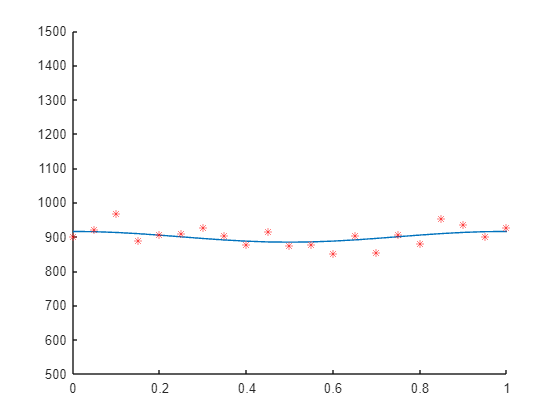

T = importdata('TempMed.mat');
n = length(T(:,1));
x = 0:0.05:1;
t = 0:60:3600;
L = 1;
alfa = 22.8*10^(-6);
lamda = alfa/L^2;

c1 =900;
c2 =999;
c3 = 100;

Temp = @(x,t) c1 + 400*cos(c2*x)*exp(-lamda*4*t*pi^2) + 100*cos(4*pi*x/L)*exp(-c3*t);

for i = 1:length(t)  
    hold on
    plot(x,Temp(x,t(i)))
    plot(x,T(i,:),'r*')
    ylim([500 1500])
    hold off
    pause(0.1)
    if i ~= length(t)
        clf
    end    
end

t = 0:60:3600;
J = zeros(3); % inicialización de la matriz de jacobianos
F = zeros(3,1); % inicialización del vector de funciones

dc1 = 0.5;
dc2 = 0.5;
dc3 = 0.5;
Contador = 0;

Tol = 0.01; Nmax = 10;
%while any(F >= Tol) && Contador < NMax
for k = 1:3
    for i = 1:61
        for j = 1:21

            % Terminos generales de las sumatorias
            f1 = @(c1,c2,c3) ((-2*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281);
            f2 = @(c1,c2,c3) (800*x(j).*exp(-lamda*pi^2*4*t(i))*sin(c2*x(j))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;
            f3 = @(c1,c2,c3) (200*t(i)*cos(4*pi/L*x(j))*exp(-lamda*pi^2*4*t(i))*(T(i,j) - c1 - 400*cos(c2*x(j))*exp(-lamda*pi^2*4*t(i)) - 100*cos(4*pi*x(j)/L)*exp(-c3*t(i))))/1281;

            %%%%%%%%%%%%%%%%% Matriz de jacobianos %%%%%%%%%%%%%%%%%%%
            J(1,1) = J(1,1) + (f1(c1 + dc1,c2,c3) - f1(c1,c2,c3))/dc1;
            J(1,2) = J(1,2) + (f1(c1,c2 + dc2,c3) - f1(c1,c2,c3))/dc2;
            J(1,3) = J(1,3) + (f1(c1,c2,c3 + dc3) - f1(c1,c2,c3))/dc3;
            J(2,1) = J(2,1) + (f2(c1 + dc1,c2,c3) - f2(c1,c2,c3))/dc1;
            J(2,2) = J(2,2) + (f2(c1,c2 + dc2,c3) - f2(c1,c2,c3))/dc2;
            J(2,3) = J(2,3) + (f2(c1,c2,c3 + dc3) - f2(c1,c2,c3))/dc3;
            J(3,1) = J(3,1) + (f3(c1 + dc1,c2,c3) - f3(c1,c2,c3))/dc1;
            J(3,2) = J(3,2) + (f3(c1,c2 + dc2,c3) - f3(c1,c2,c3))/dc2;
            J(3,3) = J(3,3) + (f3(c1,c2,c3 + dc3) - f3(c1,c2,c3))/dc3;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
            %%% Vector de funciones %%%
            F(1) = F(1) + f1(c1,c2,c3);
            F(2) = F(2) + f2(c1,c2,c3);
            F(3) = F(3) + f3(c1,c2,c3);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%
        end
    end 
    fprintf('########## Inicio de la iteracion %d ##########',k)
    J
    F
    dC = J^1 * F
    c1 = c1 - dC(1)
    c2 = c2 - dC(2)
    c3 = c3 - dC(3)
    Contador = Contador + 1
    fprintf('##############################################')
end

########## Inicio de la iteracion 1 ##########

J = 1.0e+05 *

    0.0000   -0.0004         0
   -0.0004    0.0928         0
   -0.0269   -2.6161         0


F = 1.0e+05 *

   -0.0000
   -0.0039
    1.7816


dC = 1.0e+08 *

    0.0002
   -0.0360
    1.0135


c1 = -1.4138e+04

c2 = 3.5961e+06

c3 = -1.0135e+08

Contador = 1

##############################################

########## Inicio de la iteracion 2 ##########

J =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


F =    NaN
   NaN
  -Inf


dC =    NaN
   NaN
   NaN


c1 = NaN

c2 = NaN

c3 = NaN

Contador = 2

##############################################

########## Inicio de la iteracion 3 ##########

J =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


F =    NaN
   NaN
   NaN


dC =    NaN
   NaN
   NaN


c1 = NaN

c2 = NaN

c3 = NaN

Contador = 3

##############################################